%Starts on page 119 In Wiley Textbook

%Aerodynamic

%Resources Used

T-37A Flight Manual

Napolitano Textbook

Wiley Textbook

## Typical flight conditions 

altitude = 30000; %ft
M = 0.459; %mach number
Vp1 = 456; %ft/sec
qbar1 = 92.7; %lbs/ft^2
AoA = 2; %angle of attack
S = 182; %ft^2 
cbar = 5.47; %ft
b = 33.8; %ft
Xcg = 0.27; 
W = 6360; %lbs
% Define variables with their corresponding values

## Table Values for the T-37A

% Variables with numerical values
A_ft = 12.4;
XHV_ft = 1.5;
B_ft = 33.8;
XWHr_ft = 15.9;
BH_ft = 14.0;
X1_ft = 26.6;
BV_ft = 4.8;
YAI_ft = 9.9;
C_ft = 5.5;
YAO_ft = 16.6;
CAileron_ft = 1.2;
YRI_ft = 0;
cbarR_ft = 1.4;
YRF_ft = 4.4;
CWingAtAileron_ft = 4.9;
YV_ft = 1.7;
CR_ft = 6.2;
ZH_ft = -3.1;
CRH_ft = 4.6;
ZRS_ft = 3.6;
CRV_ft = 6;
Z1_ft = 4.3;
CT_ft = 4.5;
Z2_ft = 2.1;
CTH_ft = 2.2;
ZHS_ft = 23.1;
CTV_ft = 2.5;
Zmax_ft = 4.4;
D_ft = 4;
ZW_ft = 0;
LB_ft = 29.2;
ZWHr_ft = 3;
LCG_ft = 11.4;
GammaH_rad = deg2rad(0);
r1_ft = 2.2;
GammaW_rad = (3);
S_ft2 = 182;
EpsilonH_rad = deg2rad(2); % Assumed
SBS_ft = 80.2;
EpsilonW_rad = deg2rad(2); % Assumed
SfAVG_ft2 = 8.7;
LambdaLE_rad = deg2rad(1.5);
SPV_ft2 = 1.9;
LambdaLEH_rad = deg2rad(12.5);
Wmax_ft = 9;
XACR_ft = 5.1;
xbarCG = .27

xbarCG = 0.2700


LambdaLE_rad_half = tan(LambdaLE_rad) - (((4*.5)*(1-lambda))/(AR*(1+lambda)))

LambdaLE_rad_half = -0.0244

LambdaLE_rad_quarter = tan(LambdaLE_rad) - (((4*.25)*(1-lambda))/(AR*(1+lambda)))

LambdaLE_rad_quarter = 8.7442e-04


LambdaLEV_rad = deg2rad(33);
lambdaV = (CTV_ft/CRV_ft);
lambda = .7258;
AR = 6.2771;
lambdaH = CTH_ft/CRH_ft;
SH = (BH_ft/2)*(CRH_ft)*(1+lambdaH)

SH = 47.6000

ARH = (BH_ft^2)/SH;

LambdaLEH_rad_half = tan(LambdaLEH_rad) - (((4*.5)*(1-lambdaH))/(ARH*(1+lambdaH)))

LambdaLEH_rad_half = 0.0503

LambdaLEH_rad_quarter = tan(LambdaLEH_rad) - (((4*.25)*(1-lambdaH))/(ARH*(1+lambdaH)))

LambdaLEH_rad_quarter = 0.1360










eta_H = 0.9;
eta_V = 0.9;
tau_E = 0.5;

Kint = 0; %Slide 28, lecture 8.1, this is zero because  the location of quarter chord and the fuselage center line have no difference in height

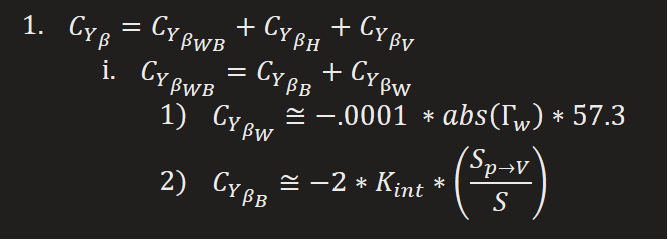




%S_H = (BH_ft^2)/AR_
C_Y_beta_W = -.0001 * abs((GammaW_rad)) * 57.3 

C_Y_beta_W = -0.0172

C_Y_beta_B = 0 %appears to be zero from figure C-A10.5

C_Y_beta_B = 0

dsigma_dbeta = 0;
xaxis_for_K_Y_V = BV_ft/(2*r1_ft)

xaxis_for_K_Y_V = 1.0909

C_Y_beta_H = 0%-.0001*abs(GammaH_rad)*57.3*(.724+3.06*((S)) % Need S_H and AR_H to move ahead, where do I get these? -> assumed negligible for normal aircraft on page 142 

C_Y_beta_H = 0

K_Y_V = 0.75; %Chart on page 143 



S_V = (BV_ft/2)*CRV_ft*(1+(CTV_ft/CRV_ft)) %Page 207 Napotilano

S_V = 20.4000

AR_V = (BV_ft^2)/S_V;
LambdaV = tan(LambdaLEV_rad) - ((4*(1-lambdaV))/(AR_V*(1+lambdaV)))

LambdaV = -0.8089

LambdaLEV_rad_half= tan(LambdaLEV_rad) - (((4*.5)*(1-lambdaV))/(AR_V*(1+lambdaV)))

LambdaLEV_rad_half = -0.0798

LambdaLEV_rad_quarter = tan(LambdaLEV_rad_half) - (((4*.25)*(1-lambdaV))/(AR_V*(1+lambdaV)))

LambdaLEV_rad_quarter = -0.4445


k_V = 1 + ((8.2 - (2.3*LambdaLEV_rad) - (AR_V*(0.22-(.153*LambdaLEV_rad))))/100); %Need for C_L_alpha_V

%need c1 and c2 from figure 4.15, using BV_ft/(2*r1_ft) and lambdaV
c1_x_axis = BV_ft/(2*r1_ft)

c1_x_axis = 1.0909

disp("λ_V=" + lambdaV)

λ_V=0.41667


c1 = 1.56;
%Neeed X_AC_H->V / cbar_V for lines, and Z_H / b_V
c2_x_axis = ZH_ft/BV_ft

c2_x_axis = -0.6458

X_AC_H_to_V = 1.5; %Need to verify this, I am not sure based on the drawing - Koko / Krishna
cbarV = 2.5 %Need to verify this as well, not sure based off the drawing, 

cbarV = 2.5000

c2line = X_AC_H_to_V/cbarV

c2line = 0.6000

c2 = .92;

%need S_H now for K_HV
S_H = 46.57 %ft squared, from T-37A manual

S_H = 46.5700

KHV_x_axis = S_H/S_V

KHV_x_axis = 2.2828

K_HV = 1.16; %x-axis value is technically off the chart, this is an estimate. The equation on page 145 at the bottom for twin vertical tails may need to be used here. 

%K_HV = 
AR_V_eff = c1 * AR_V * (1+K_HV*(c2-1))

AR_V_eff = 1.5984


C_L_alpha_V = (2*pi*AR_V_eff)/(2 + sqrt(((AR_V_eff*(1-M^2))/(k_V))*(1+((tan(LambdaLEV_rad_half)^2)/(1-M^2)))+4)) %Polhamus Formula in chaoter 2 using vertical tail specifc values

C_L_alpha_V = 2.3473


C_Y_beta_V = -K_Y_V * abs(C_L_alpha_V) * (.724 + 3.06 *((S_V/S)/(1+cos(LambdaLEV_rad_quarter))) + 0 + .009 * AR_V)

C_Y_beta_V = -1.6098


C_Y_beta = C_Y_beta_W + C_Y_beta_B + C_Y_beta_H  + C_Y_beta_V %Check with Koko

C_Y_beta = -1.6270


C_Y_delta_A = 0; % "The forces associated with the asymmetric defiections of the left and right. ailerons act along the vertical and 
                 %horizontal directions; therefore, their components along
                 %the lateral direction are negligible. C_Y_δ_A is about 0

%Need tau_R using cbar_rudder / cbar_verttail
tau_R_x_axis = cbarR_ft/cbarV

tau_R_x_axis = 0.5600

tau_R = .75

tau_R = 0.7500

%Need K_R from figure 4.27 
disp(lambdaV)

    0.4167



K_R = .95 %Need to verify with Koko, could also be zero since there is no difference. Used lambdaV ~= to 0.5

K_R = 0.9500


C_Y_delta_R = abs(C_L_alpha_V) *eta_V*(S_V/S)*K_R*tau_R

C_Y_delta_R = 0.1687




C_n_beta = 0;


C_n_delta_A =0;
C_n_delta_R = 0;

C_l_beta = 0;
c_L_1 = 0; %Need to calculate 


$$c_{l\textrm{𝛽}} =c_{l{\textrm{𝛽}}_{WB} \ } +c_{l_{{\textrm{𝛽}}_H } } +c_{l{\textrm{𝛽}}_V } \$$



$$c_{{l_{\textrm{𝛽}} }_{WB} } =\;57\ldotp 3\ast c_1 {\left[{{\left(\frac{c_{l_{\textrm{𝛽}} } }{c_{L_1 } }\right)}}_{\Lambda_{\frac{c}{2}} } K_{M_A } K_f +{{\left(\frac{c_{l_{\textrm{𝛽}} } }{c_{L_1 } }\right)}}_{AR} \right]}+57\ldotp 3{\left\{\Gamma_W {\left[\frac{c_{l_{\textrm{𝛽}} } }{\Gamma_W }K_{M_{\Gamma } } +\frac{\Delta c_{l_{\textrm{𝛽}} } }{\Gamma_W }\right]}+{{\left(\Delta c_{l_{\textrm{𝛽}} } \right)}}_{Z_W } +{\textrm{𝜀}}_W \tan {\left(\Lambda_{\frac{c}{4}} \right)}{\left(\frac{\Delta c_{l_{\textrm{𝛽}} } }{{\textrm{𝜀}}_W \tan {\left(\Lambda_{\frac{c}{4}} \right)}}\right)}\right\}}$$


dB = sqrt(SfAVG_ft2/(pi/4)) %diameter of the fuselage

dB = 3.3282

delta_clbeta_over_Gamma_W = -.0005 * AR * ((dB/B_ft)^2)

delta_clbeta_over_Gamma_W = -3.0432e-05

delta_clbeta_ZW = ((1.2*sqrt(AR)))

delta_clbeta_ZW = 3.0065

%c_l_beta_WB_piece1 = 57.3*c1 *(())
%c_l_beta_WB_piece2 = 
%c_l_beta_WB = c_l_beta_WB_piece1 + c_l_beta_WB_piece2 %current stopping point and the equations above 





C_l_delta_A =0;
C_l_delta_R = 0;



$$c_{l_p } =c_{l_{p_{WB} } } +c_{l_{p_H } } +c_{l_{PV} } \$$


- Using Figure 4.81 use λ = 0.5, 

- FEO stands for 4.81

%c_l_p_W
k_W = 1 + ((8.2 - (2.3*rad2deg(LambdaLE_rad)) - (AR*(0.22-(.153*(rad2deg(LambdaLE_rad))))))/100) %Wrong Equation

k_W = 1.0481


beta = sqrt(1-M^2)

beta = 0.8884

ChartLinesFEO = (beta * AR)/k

ChartLinesFEO = 5.3209

xAxisFEO = atan(rad2deg(LambdaLE_rad_quarter) / (sqrt(1-M^2))) 

xAxisFEO = 0.0563

RDP = -.360; % Read from Figure 4.81
c_l_p_W = RDP * (k/beta)

c_l_p_W = -0.4247

%c_l_p_H
k_H = 1 + ((8.2 - (2.3*rad2deg(LambdaLEH_rad)) - (AR*(0.22-(.153*(rad2deg(LambdaLEH_rad))))))/100)

k_H = 0.9007

beta_H = sqrt(1-M^2) 

beta_H = 0.8884

%disp('λ_Η = ' + lambdaH)
ChartLinesFEO2 = (beta_H * ARH)/k_H 

ChartLinesFEO2 = 4.0614

xAxisFEO2 = atan(rad2deg((LambdaLEH_rad_quarter)) / (sqrt(1-M^2)))

xAxisFEO2 = 1.4573

c_l_p_H = (0.5*c_l_p_W)*(S_H/S)*(BH_ft/B_ft)^2 

c_l_p_H = -0.0093


$$c_{l_{p_V } } \cong 2\ \ast c_{Y_{{\mathrm{𝛽}}_{\mathrm{V}} } } {{\left(\frac{Z_v }{b}\right)}}^2$$


% Need Z_V , obtained from Figure C-A10.5 of the airplane data sheet,
% T37-A_aircraft pdf
Z_V = 4.8

Z_V = 4.8000

c_l_p_V = 2 * C_Y_beta_V * ((Z_V/b)^2)

c_l_p_V = -0.0649

c_l_p = c_l_p_W + c_l_p_H + c_l_p_V % 1.3% off the actual value TA has

c_l_p = -0.4989


C_Y_p = 0; %Need to do 

C_n_p = 0; 

C_l_r = 0;
C_Y_r = 0;
C_n_r = 0;


